Playing hod_m.wav at 24000 Hz with duration 0.22 seconds and 5380 samples


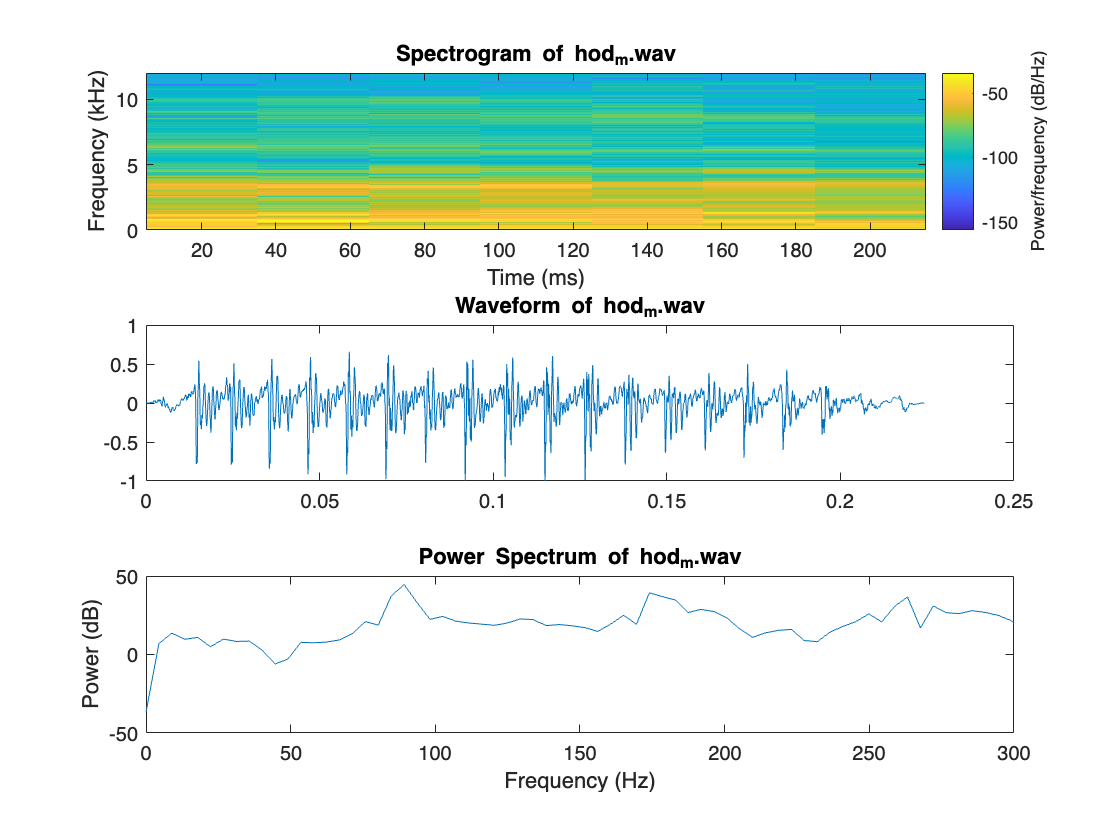

file_1 = 'hod_m.wav';
[audio, fs, duration, numSamples] = playAudio(file_1);

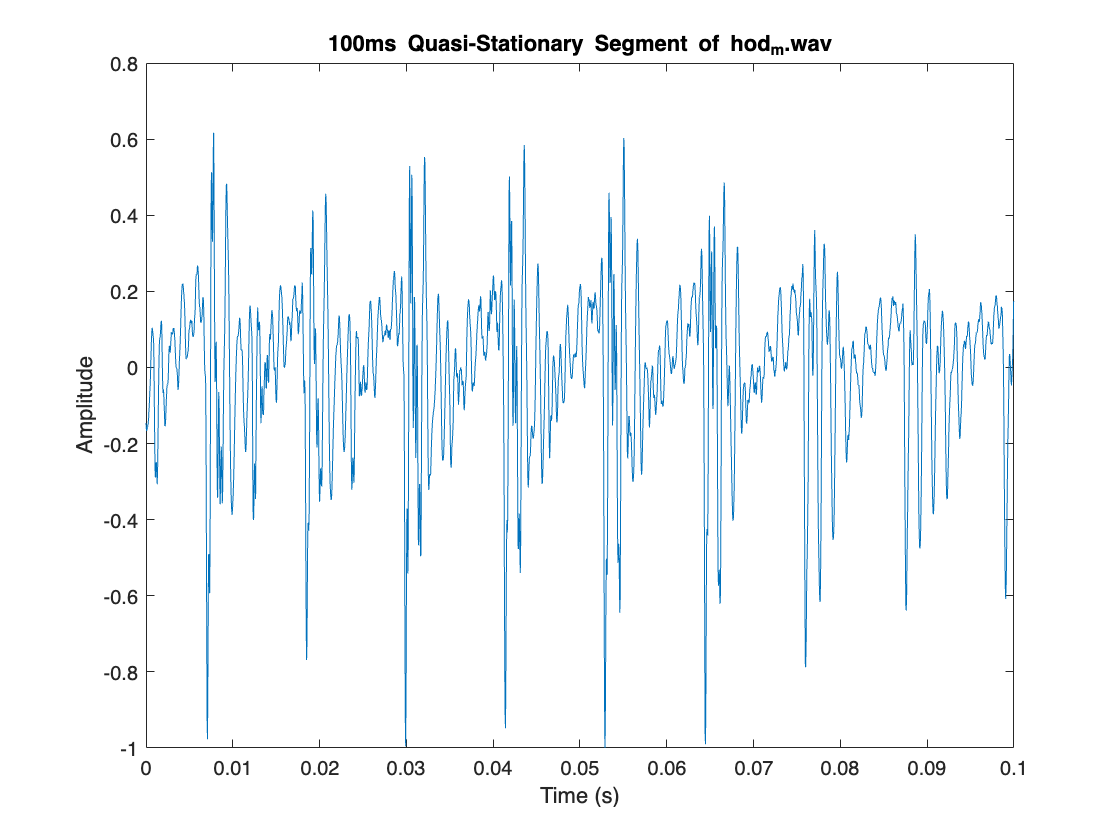

% select a 100ms quasi-stationary segment
segmentDuration = 0.1; % 100 ms
segment = extractCenterSegment(audio, fs, segmentDuration, file_1);


estimateLPC(segment, 12);

LPC Coefficients (order 12):
    1.0000   -2.2509    1.7988   -0.5725    0.3362   -0.7482    0.6225   -0.2059    0.0254    0.2358   -0.2016   -0.0661    0.0676




% coefficients.
% impulse train is generated using fundamental frequencies (try sawtooth)